# **Lab 2**

# Problem 1

In lecture and homework we explored how the convolution can be used to calculate the probability of a sum or average. For this problem we are going to imagine that we are looking for gamma-ray sources (e.g. with the [Fermi telescope](https://fermi.gsfc.nasa.gov)). In this kind of telescope there is a background of cosmic-rays (electrons and protons, mostly) that provides a discrete noise term across the sky that precisely follows a Poisson distribution. To detect a gamma-ray source, you need to ask what is the probability that the cosmic-ray background would have given you a measurement as signal-like or more than the signal that you received.

To set up the problem, assume in 1 day the average cosmic-ray background is some number X (pick someting btwn 0.5 and 10, with different values for you and your lab partner); and the average number of gamma-rays emitted by your hypothetical source is Y (pick something larger than X).

A) Show how the probability distribution of the background changes as you integrate (sum) for more days.

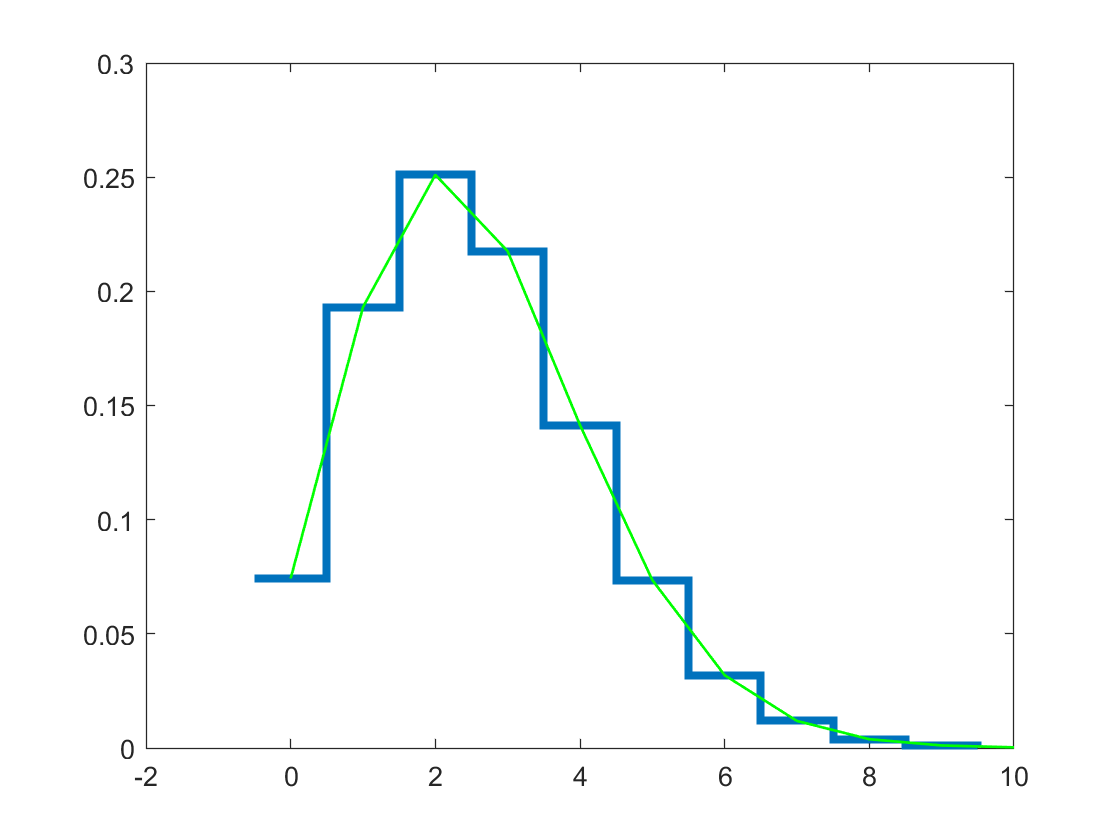

X = 2.6;
Y = 5.9;

xvals = 0:10;
poisson = makedist("Poisson","lambda",X);
funct = pdf(poisson,xvals);

stairs(xvals-0.5,funct,"LineWidth",3)
hold on
plot(xvals,funct,"LineWidth",1,"Color","green")
hold off

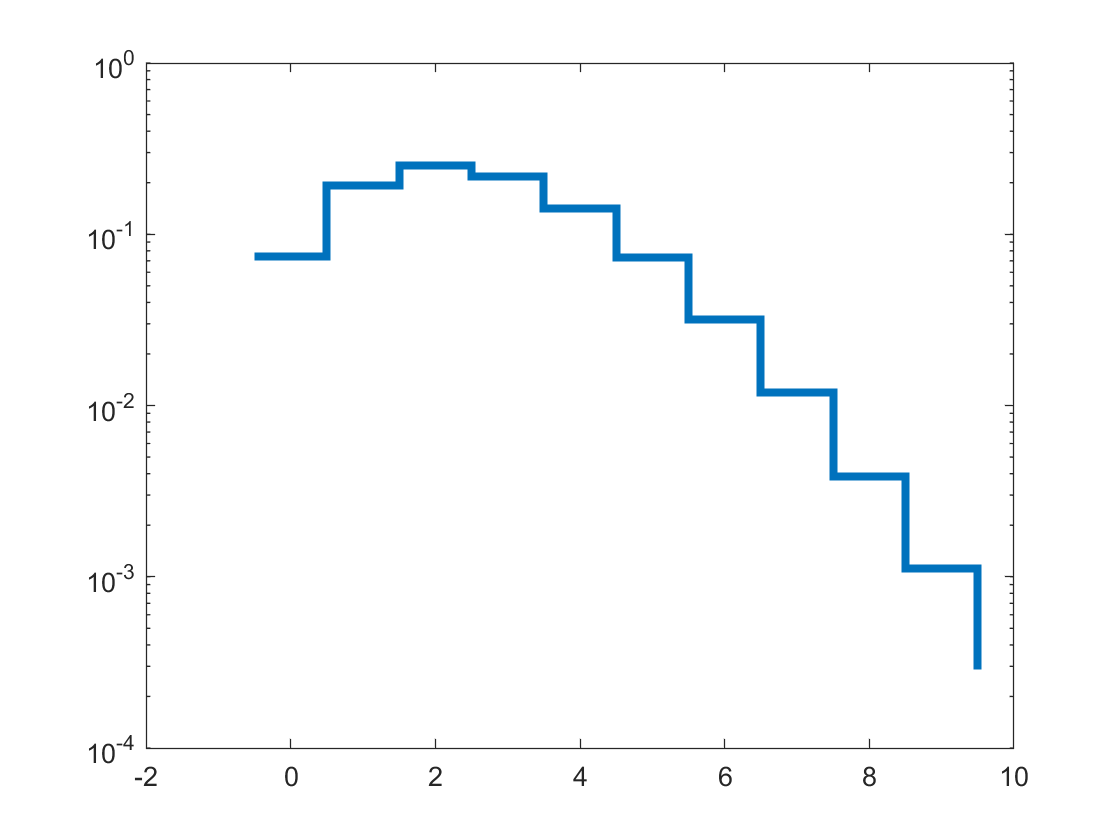


%semi-log axis
stairs(xvals-0.5,funct,"LineWidth",3)
set(gca,'YScale','log')

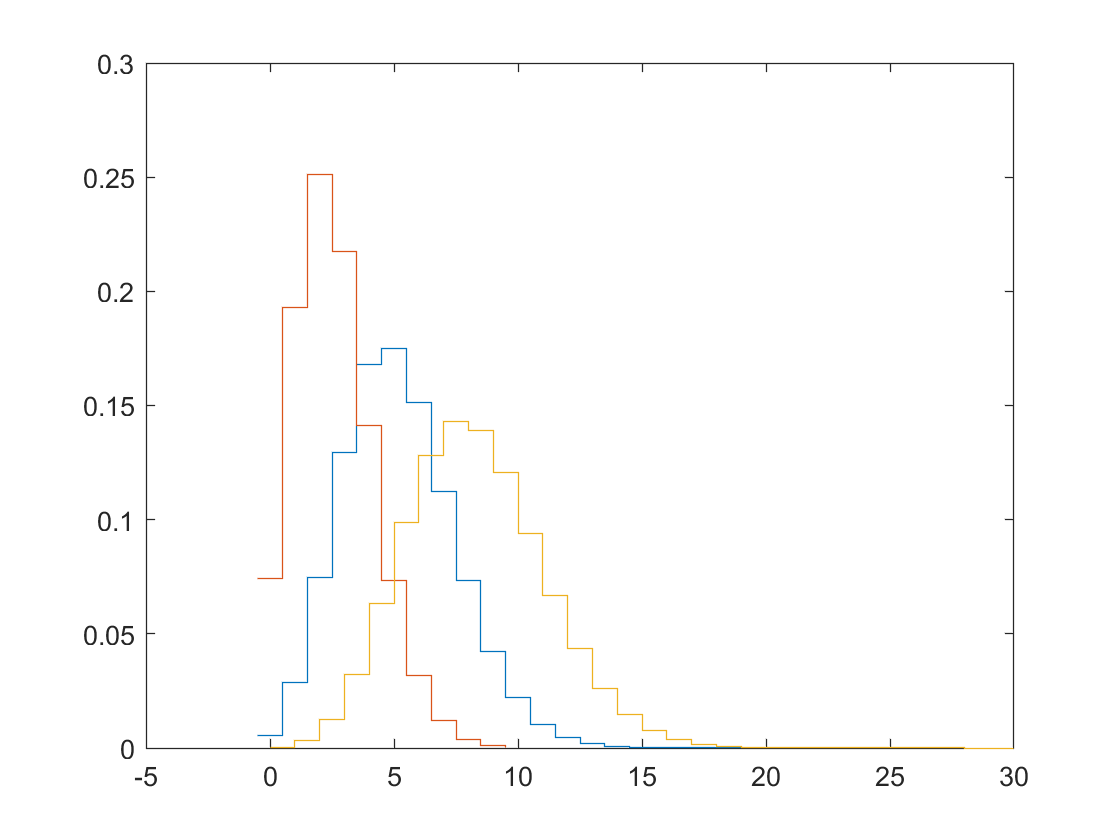


%1st convolution
convol = conv(funct,funct);

cxvals = 0:length(convol)-1;
stairs(cxvals-0.5,convol)
hold on
stairs(xvals-0.5,funct)

%2nd convolution
convol2 = conv(convol,funct);

c2xvals = 0:length(convol2)-1;
stairs(c2xvals,convol2)


sum(convol2)

ans = 0.9997

sum(convol)

ans = 0.9998

sum(funct)

ans = 0.9999

%all sums are close to 1 --> normalized :)

%mean for original distribution
weighted = zeros(1,length(xvals));

for i = 1:length(xvals)
    weighted(i) = funct(i)*xvals(i);
end

avg_val = sum(weighted)

avg_val = 2.5990


%mean for convolved dist
weighted_c = zeros(1,length(cxvals));

for i = 1:length(cxvals)
    weighted_c(i) = convol(i)*cxvals(i);
end

avg_val_c = sum(weighted_c)

avg_val_c = 5.1976


%mean for second convolution
weighted_c2 = zeros(1,length(c2xvals));

for i = 1:length(c2xvals)
    weighted_c2(i) = convol2(i)*c2xvals(i);
end

avg_val_c2 = sum(weighted_c2)

avg_val_c2 = 7.7957

**NOTE: MAKE A FOR LOOP TO CONVOLVE AND TO FIND THE AVERAGE VALUES!!!!!!**

B) Show that after 5 days, the summed probability distribution is still a Poisson distribution. Explain why this makes sense from a mathematical and conceptual point of view. 

convolution: perform 4 times

overlay with poisson with lambda of found average value

C) Show how the probability distribution evolves as you *average* days. Calculate for many different ranges of days, and explore the shape of the distribution as the number of days becomes larger. Discuss this in relation to both B) and the central limit theoem.

- average the original data points with the convolved data points and see how the graph turns out

- do several examples

- reference CLT

D) Pick some number of days N, and assume you saw Y*N gamma rays from your source. Calculate the 'sigma' of your observation. [In reality the number of gamma-rays seen from a source will also fluctuate, but we're going to ignore that complication for a couple of labs.]